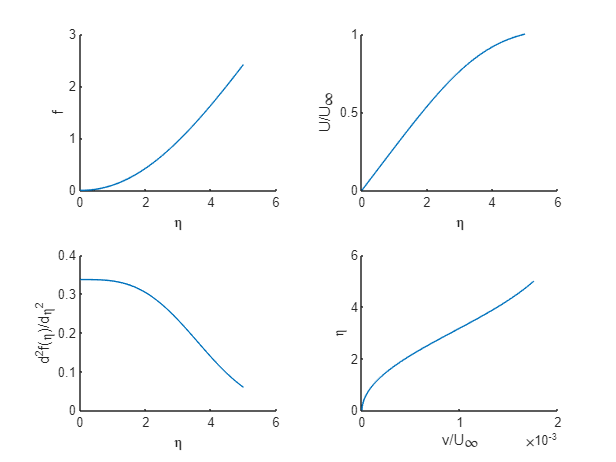

clc;
clear all;
close all;
prompt=input('Enter the Method by which you want to solve(RK4/EulerMethod)?1-RK4 , 2-Euler?');
cho=prompt; 
kin_viscosity=1.48*10e-05;
U_inf=8;

g1=10e-05;%First Guess                       

g2=0.9*10e-05;%Second Guess

prompt=input('Enter the length of the plate in units');
length=prompt; %Characteristic Length of Plate
Re=(U_inf*length)/kin_viscosity;%Reynolds No 

guess=[g1 g2];

D_size=5;
Eta=linspace(0,D_size,50);
delta=(D_size-1)/50;
f(1)=0;
g(1)=0;
v(1)=0;
err=0;

for i=1:2 
    h(1)=guess(i);
    
    for j=2:50 % Loop that calculates f',f'',f''' for the two wild guesses using RK4,Euler Method
        temp=f(j-1)*h(j-1)*-0.5;
        
        value=rungekutta4consts(delta,temp,cho);% RK 4 Method/EULER Method
        
        h(j)=h(j-1)+value;
        
        value1=rungekutta4consts(delta,h(j-1),cho);
        g(j)=g(j-1)+value1;
       
        value2=rungekutta4consts(delta,g(j-1),cho);
        f(j)=f(j-1)+value2;
        
        
    end
    err=abs(1-g(50));
    
    if err<10e-07 
        break;
    else
        g_50(i)=g(50);
        %g11(i,:)=g;
        f=zeros(1,50);
        g=zeros(1,50);
        h=zeros(1,50);
       
    end
    
end
i=1;
j=3;

while(err>10e-07)
    a=g_50(j-1)-1; % Newton Raphson Method for manipulation of the correct guess from the given two wild guesses
   
    b=guess(j-1)-guess(j-2);
    
    c=g_50(j-1)-g_50(j-2);
   
    guess(j)=guess(j-1)-(a*(b/c));
    
   
    h(1)=guess(j);
   
    for r=2:50 % Loop for finding f',f'',f''' for other guesses excluding initial two wild guess
        temp=f(r-1)*h(r-1)*-0.5;
        
        value=rungekutta4consts(delta,temp,cho);
        

        h(r)=h(r-1)+value;
        
        value1=rungekutta4consts(delta,h(r-1),cho);
        g(r)=g(r-1)+value1;
        
        value2=rungekutta4consts(delta,g(r-1),cho);
        f(r)=f(r-1)+value2;
        
    end
    err=abs(1-g(50));
    g_50(j)=g(50);
    g11(j,:)=g;
    
    j=j+1;
end
for j=1:50
    v(j)=(Eta(j)*g(j)-f(j))/(2*(Re)^0.5);
end
a=tiledlayout(2,2);
ax1=nexttile;
hold on;
plot(Eta,f);
xlabel('\eta');
ylabel('f');
hold off;
ax2=nexttile;
hold on;
plot(Eta,g);
xlabel('\eta');
ylabel('U/U\infty');
hold off;
ax3=nexttile;
hold on;
plot(Eta,h);
xlabel('\eta');
ylabel('d^2f(\eta)/d\eta^2');
hold off;
ax4=nexttile;
hold on;
plot(v,Eta);
ylabel('\eta');
xlabel('v/U\infty');
hold off;

function [val]=rungekutta4consts(del,g_int,choice)% Function for calculating RK4 constants
  if choice==1 
   k1=del*g_int;
   k2=del*(g_int+0.5*k1);
   k3=del*(g_int+0.5*k2);
   k4=del*(g_int+k3);
   val=(k1+2*k2+2*k3+k4)/6;
  end
  if choice==2
  k1=6*(del*g_int);       
  k2=0;
  k3=0;
  k4=0;
  val=(k1+2*k2+2*k3+k4)/6;
  end 
     
end 



